Controlador Proporcional

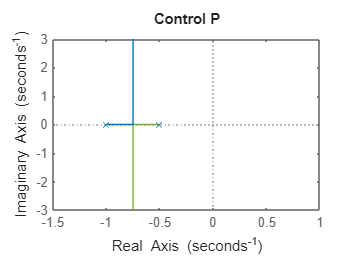

z = '';
p = [-1 -0.5];
k = 1;
[num, den] = zp2tf(z, p, k);
Gp = tf(num, den);

H = [1];
kp = 1;
Gc = tf(kp);

FTLA = Gc * Gp * H;
rlocus(FTLA);
xlim([-1.5 1]);
ylim([-3 3]);
title('Control P');